# 1.3.04. Решение жестких систем ОДУ

**Лекция**

## Введение

Жесткие системы обыкновенных дифференциальных уравнений (ОДУ) - это системы, для решения которых явные методы не работают или работают плохо, ибо теряется устойчивость. Жесткие системы достаточно часто в различных областях науки и техники: в механике, в электричестве, в биологии, в химии и т п. 

Одним из классических примеров жесткой системы является система дифференциальных уравнений Робертсона, описывающая одновременное протекание быстрых и медленных химических реакций, скорости которых отличаются в несколько порядков:

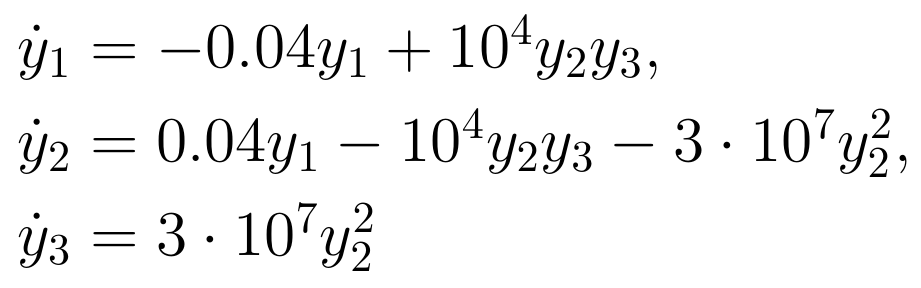

Среди решателей семейства `odeXY` есть такие, которые позволяют решать как жесткие, так и нежесткие задачи. Некоторые из них могут решать дифференциально-алгебраические системы (ДАУ) индекса 1, где часть уравнений системы не содержит производной и является алгебраической. Существует также решатель (`ode15i`), позволяющий решать полностью неявные системы. 

## Решатели семейства ode

Рассмотрим сначала нежесткие решатели.

`ode45` - реализует численный метод **Дормана-Принса** **порядка 4(5)**. Это одношаговый метод с переменным шагом. Он считается самым лучшим для решения нежестких задач. 

`ode23 `- метод **Рунге-Кутта (2,3)**, также является одношаговым методом с переменным шагом. Используется, если в задаче есть подозрение на жесткость. 

`ode113` - представитель класса методов Адамса, а именно реализует **метод Адамса-Башфорта-Мултона**. Это многошаговый метод **с переменным порядком от 1 до 12**. Использует схему предиктор-корректор для аппроксимации. Данный метод используется, когда требуется обеспечить высокую точность или когда правую часть системы вычислять долго и дорого (что особенно актуально для многомерных нелинейных правых частей). 

Теперь перейдём к рассмотрению жестких решателей. 

`ode15s` - это метод, использующий так называемые Формулы Численного Дифференцирования (numerical differentiation formulas, NDF) до 5-го порядка включительно. Однако этот решатель может также работать по Формулам Дифференцирования Назад (ФДН), если включить опцию `'BDF'` - `'on'`. Эта опция по умолчанию выключена. Этот решатель стоит использовать, если ode45 и ode23 не справляются и/или неэффективны и задача является умеренно жесткой. Этот решатель также может решать ДАУ. 

Рассмотренный метод, как впрочем и все представленные далее методы для решения жестких задач на каждой итерации расчитывают якобиан. И для этих решателей доступна возможность задавать якобиан в аналитическом виде вручную. Вы можете создать функцию возвращающую матрицу-якобиан и задать её в качестве параметра опции 'Jacobian', тем самым увеличивая скорость работы метода. Если эту опцию не задавать, то якобиан будет вычисляться приближённо посредством аппроксимации. 

`ode23s` представляет собой решатель, реализующий метод Розенброка 2-го порядка. Его следует использовать для решения систем, у которых жесткость явно выражена. В частности, если ode15s не справляется с задачей, то следует использовать именно этот решатель. Следует отметить, что этот метод имеет не очень хорошую точность расчета. 

`ode23t` реализует метод трапеций. Он предназначен для задач умеренной жесткости. Он работает быстрее ode15s, однако осуществляет некоторое демпфирование решения, из-за чего колебания решения могут быть упущены. Данный решатель также подходит для ДАУ, но тем не менее является "вторичным" по отношениюк ode15s. 

`ode23tb` - это метод, комбинирующий методы ФДН и трапеций. Он, как и ode23s и ode23t может быть более эффективен, чем ode15s при более слабых требованиях точности. 

## Сравнение жестких решателей ode. 

Решатель ode15s пригоден для большинства жестких задач. Однако некоторые задачи эффективнее решать другими решателями. Давате рассмотрим пример жесткого дифференциального уравнения всеми 4-мя решателями. 

Пусть уравнение имеет вид $y' = -\lambda y.$ Жесткость этого уравнения возрастает с ростом параметра $\lambda$. Давайте положим $\lambda = 1 \times 10^9$ и начальным условием $y(0)=1$ на интервале времени `[0 0.5]`. С такими условиями уравнение достаточно жесткое, чтобы решатели `ode45` и `ode23` затратили слишком много усилий для его решения. Также зададим Якобиан указанным выше способом: $J = \frac{\partial f}{\partial y} = - \lambda$ и будем отображать статистику для каждого решателя с помощью опции `'Stats'`:

lambda = 1e9;
y0 = 1;
tspan = [0 0.5];
opts = odeset('Jacobian',-lambda,'Stats','on');

Решим уравнения решателями `ode15s`, `ode23s`, `ode23t` и `ode23tb`:

subplot(2,2,1)
tic, ode15s(@(t,y) -lambda*y, tspan, y0, opts), toc

104 successful steps
1 failed attempts
212 function evaluations
0 partial derivatives
21 LU decompositions
210 solutions of linear systems
Elapsed time is 0.412993 seconds.


title('ode15s')
subplot(2,2,2)
tic, ode23s(@(t,y) -lambda*y, tspan, y0, opts), toc

63 successful steps
0 failed attempts
191 function evaluations
0 partial derivatives
63 LU decompositions
189 solutions of linear systems
Elapsed time is 0.140058 seconds.


title('ode23s')
subplot(2,2,3)
tic, ode23t(@(t,y) -lambda*y, tspan, y0, opts), toc

95 successful steps
0 failed attempts
125 function evaluations
0 partial derivatives
28 LU decompositions
123 solutions of linear systems
Elapsed time is 0.181801 seconds.


title('ode23t')
subplot(2,2,4)
tic, ode23tb(@(t,y) -lambda*y, tspan, y0, opts), toc

71 successful steps
0 failed attempts
167 function evaluations
0 partial derivatives
23 LU decompositions
236 solutions of linear systems
Elapsed time is 0.182296 seconds.


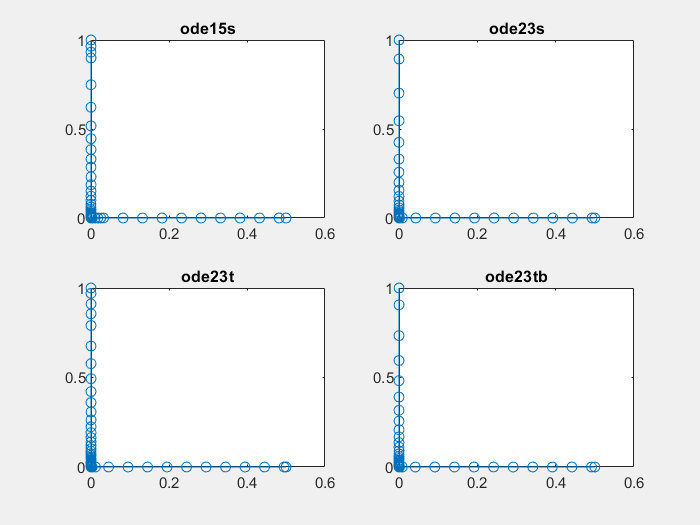

title('ode23tb')

Наилучшим образом к данной задаче, как видно, подходит решатель ode23s, ибо он выполняется быстрее всего и за наименьшее количество шагов. 